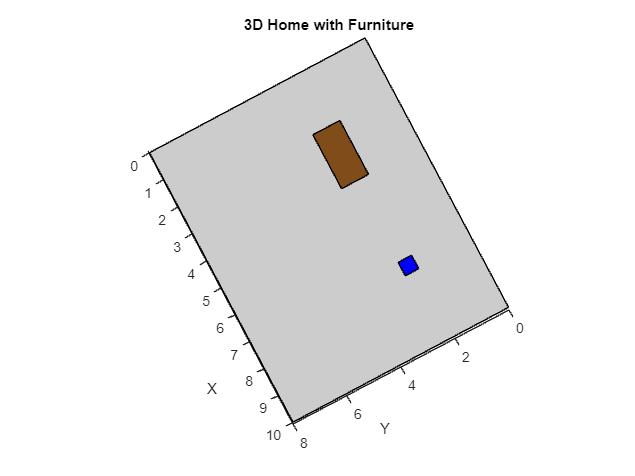

% Define room dimensions
room_length = 10; % in meters
room_width = 8;   % in meters
room_height = 3;  % in meters

% Create room walls
room_walls = [
    0, 0, 0;          % Corner 1
    room_length, 0, 0;% Corner 2
    room_length, room_width, 0;% Corner 3
    0, room_width, 0;% Corner 4
    0, 0, room_height;% Corner 5
    room_length, 0, room_height;% Corner 6
    room_length, room_width, room_height;% Corner 7
    0, room_width, room_height;% Corner 8
];

% Define wall faces
wall_faces = [
    1, 2, 3, 4;  % Floor
    5, 6, 7, 8;  % Ceiling
    1, 2, 6, 5;  % Wall 1
    2, 3, 7, 6;  % Wall 2
    3, 4, 8, 7;  % Wall 3
    4, 1, 5, 8]; % Wall 4

% Create table
table_width = 1;
table_length = 2;
table_height = 0.8;

table_vertices = [
    2, 2, 0;  % Bottom-left corner
    2+table_length, 2, 0;  % Bottom-right corner
    2+table_length, 2+table_width, 0;  % Top-right corner
    2, 2+table_width, 0;  % Top-left corner
    2, 2, table_height;  % Bottom-left corner (height)
    2+table_length, 2, table_height;  % Bottom-right corner (height)
    2+table_length, 2+table_width, table_height;  % Top-right corner (height)
    2, 2+table_width, table_height;  % Top-left corner (height)
];

table_faces = [
    1, 2, 3, 4;  % Table top
    5, 6, 7, 8;  % Table bottom
    1, 2, 6, 5;  % Side 1
    2, 3, 7, 6;  % Side 2
    3, 4, 8, 7;  % Side 3
    4, 1, 5, 8]; % Side 4

% Create chair
chair_width = 0.5;
chair_length = 0.5;
chair_height = 1;

chair_vertices = [
    7, 2, 0;  % Bottom-left corner
    7+chair_length, 2, 0;  % Bottom-right corner
    7+chair_length, 2+chair_width, 0;  % Top-right corner
    7, 2+chair_width, 0;  % Top-left corner
    7, 2, chair_height;  % Bottom-left corner (height)
    7+chair_length, 2, chair_height;  % Bottom-right corner (height)
    7+chair_length, 2+chair_width, chair_height;  % Top-right corner (height)
    7, 2+chair_width, chair_height;  % Top-left corner (height)
];

chair_faces = [
    1, 2, 3, 4;  % Chair seat
    5, 6, 7, 8;  % Chair bottom
    1, 2, 6, 5;  % Side 1
    2, 3, 7, 6;  % Side 2
    3, 4, 8, 7;  % Side 3
    4, 1, 5, 8]; % Side 4

% Plot room
figure;
hold on;

for i = 1:size(wall_faces, 1)
    patch('Vertices', room_walls, 'Faces', wall_faces(i, :), 'FaceColor', [0.8 0.8 0.8], 'FaceAlpha', 1);
end

% Plot table
for i = 1:size(table_faces, 1)
    patch('Vertices', table_vertices, 'Faces', table_faces(i, :), 'FaceColor', [0.5 0.3 0.1], 'FaceAlpha', 1);
end

% Plot chair
for i = 1:size(chair_faces, 1)
    patch('Vertices', chair_vertices, 'Faces', chair_faces(i, :), 'FaceColor', [0 0 1], 'FaceAlpha', 1);
end

axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('3D Home with Furniture');
view(3);
grid on;
hold off;

view([-55.99 -90.00])